# Dealing with 60 Hz

60 Hz is ubiquitious in electronics. This unit explores how to reduce 60Hz interference while detecting weak signals (of other frequencies), and also how to measure just 60Hz in the presence of noise at other frequencies. We'll begin both by simulation of data + noise, which gives us the advantage of knowing *a priori* the signal to noise ratio (SNR). 

## 1. Measuring DC in the presence of 60 Hz

We know that averaging multiple measurements should reduce the influence of noise, so lets average 100 data points (is that enough?): 

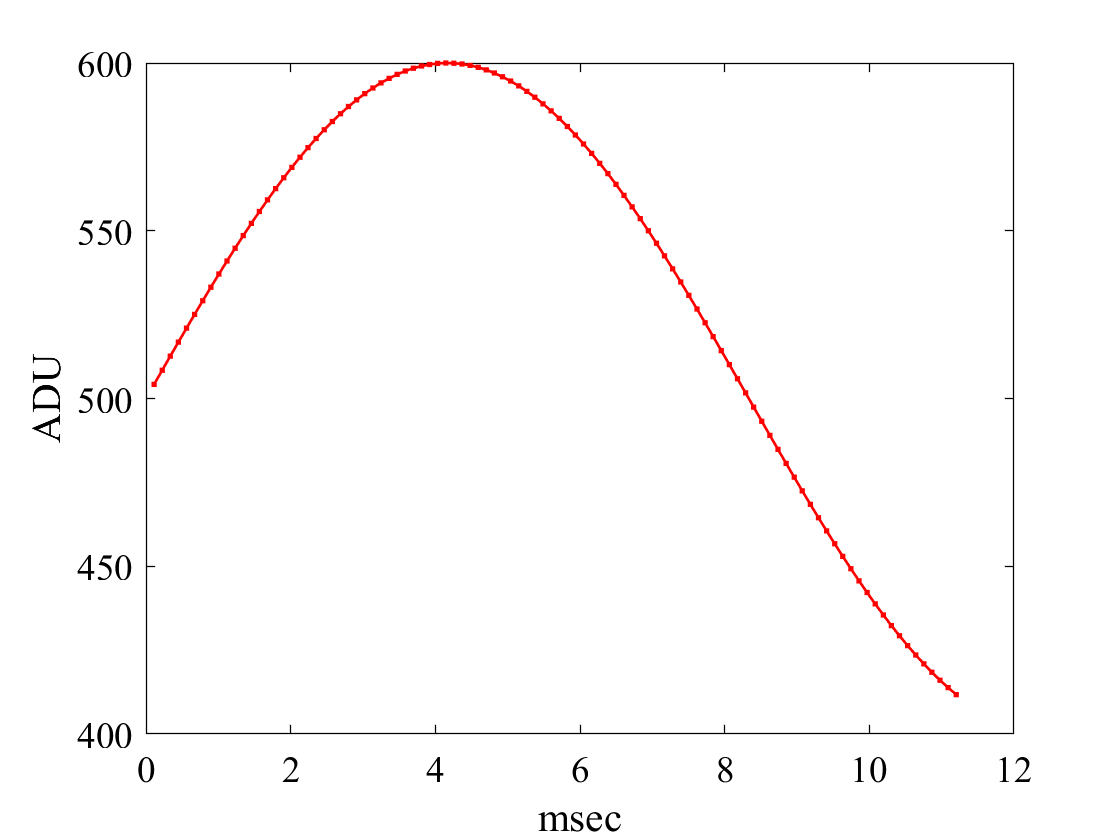

sr = 8.9274e+03; % Arduino single channel sample rate (Hz)
an = 100; % amplitude of 60 Hz noise (ADU)
signal = 500; % amplitude of DC signal (ADU)
numPts = 100;
t = [1:numPts]' / sr; % seconds
noise = an * sin(t * 2 * pi * 60); % just 60Hz noise
data = signal + noise;
plot(t*1000,data,'.-');
xlabel('msec'); ylabel('ADU');

mean(data)

ans = 534.3692

fprintf('percent error = %.1f',(mean(data)-signal)/signal*100);

percent error = 6.9

It should be pretty clear what's wrong -- the first 74 of the 100 data points have positive noise. If we modeled a random phase for the 60 Hz (which would likely be the case in the "real world", we might get luckier and have half the data points with positive noise so it perfectly cancels, but that's very unlikely. So how can we improve our odds of getting the noise to cancel? 

**Question 1. **How many samples should be averaged so the 60 Hz noise will be zero, regardless of phase? 

numPts = round(sr/60)

numPts = 149

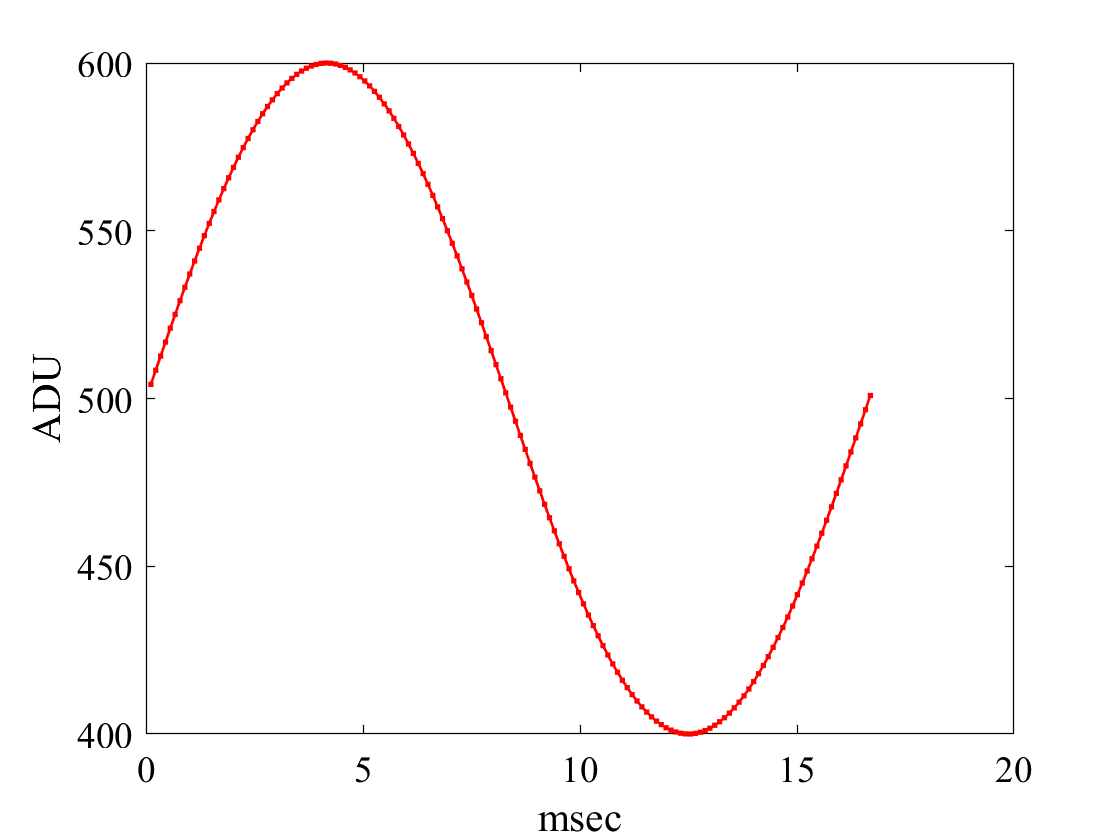

t = [1:numPts]' / sr; % seconds
noise = an * sin(t * 2 * pi * 60); % just 60Hz noise
data = signal + noise;
plot(t*1000,data,'.-');
xlabel('msec'); ylabel('ADU');

mean(data)

ans = 500.0036

fprintf('percent error = %.1f',(mean(data)-signal)/signal*100);

percent error = 0.0

What if your Arduino sample clock is different, is there another way? 

noise = randn(1e5,1);
     % 1000 periods of 60 Hz
sixty = sin(2*pi *[1:1e5]' / 100); data = noise + sixty; plot(data(1:400));
xlabel('sample #'); ylabel('voltage')
std([noise sixty data]) 

ans =

0.9985 0.7071 1.2222

m50 = mean(reshape(data, 50, 1e5/50)); % average over 1/2 cycle
m100 = mean(reshape(data,100,1e5/100)); % average over 1 60 Hz cycle % average over 50 random phases
d = reshape(data,100,1e5/100);
for i=1:1000, r50(i) = mean(d(randperm(100,50),i)); end
[std(data) std(m50) std(m100) std(r50)]

ans =

1.2222 0.6494 0.1003 0.1554